## Content

1.    绘制交叉点不符值平差前后频率分布图

2.    绘制格网

3.    Plotting deleted points those are far away from the track.\

4.    绘制FFM方法与IAM方法得到的有效值的频率分布图

### 1.    绘制交叉点不符值平差前后频率分布图

raw=rawData;

figure;
box on;
hold on;
set(gca,'FontName','Arial');
set(gca,'FontSize',14);
edges = (-1.15:0.05:1.15);
h1 = histogram(raw(:,3),edges);
h2 = histogram(adj1(:,3),edges);
h3 = histogram(adj2(:,3),edges);
% h1.FaceColor = [251 197 49]/255;
% h2.FaceColor = [232 65 24]/255;
h3.FaceColor = [190 190 190]/255;
h2.FaceAlpha = 0.8;
h3.FaceAlpha = 0.7;
legend('Before Adjustment','Overall Adjustment','Posteriori Adjustment');
ylabel('Frequency');
xlabel('Crossover difference /m');


figure;
hold on ;
box on;
set(gca,'FontName','Arial');
set(gca,'FontSize',14);
a1=histfit(raw(:,3),30);
set(a1(1),'Visible','Off');
set(a1(2),'Color',[0 0.4470 0.7410]); %曲线为绿色
set(a1(1),'handlevisibility','off');
a2=histfit(adj1(:,3),30);
set(a2(1),'Visible','Off');
set(a2(2),'Color',[0.8500 0.3250 0.0980]); %曲线为绿色
set(a2(1),'handlevisibility','off');
a3=histfit(adj2(:,3),30);
set(a3(1),'Visible','Off');
set(a3(1),'handlevisibility','off');
set(a3(2),'Color',[190 190 190]/255); %曲线为绿色
ylim([0 2100]);
xlim([-2 +2]);
legend('Before Adjustment','Overall Adjustment','Posteriori Adjustment');
ylabel('Frequency');
xlabel('Crossover difference /m');

### 2.    绘制格网

% 绘制单个格网位置
figure;
load(strcat(strcat('.\Variate\',Region,'\'),Region,'Boundary.mat'));
plot(Boundary(1:end,1),Boundary(1:end,2),'k','MarkerSize',0.01,'HandleVisibility','off'); 



grid=GridCro1_2000(374);

long=grid.long;
lat=grid.lat;
w=grid.longGap;
h=0.045;

x=long-w/2;
y=lat-h/2;
hold on;
scatter(long,lat,4,'filled');
rectangle('Position',[x,y,w,h],'LineWidth',1);  %从点(x,y)开始绘制一个宽w高h的矩形，


% 绘制所有格网
figure;
plot(Boundary(:,1),Boundary(:,2));
hold on;

for i=1:size(rossGridEdited,1)
    long=rossGridEdited(i).long;
    lat=ones(size(long))*rossGridEdited(i).lat;
    scatter(long,lat,4,'filled');
end
for i=1:size(rossGridEdited,1)   
     disp(i);
     long=rossGridEdited(i).long;
     lat=ones(size(long))*rossGridEdited(i).lat;
     scatter(long,lat,4,'filled');
     w=rossGridEdited(i).longInterval;
     h=0.045;
     for j=1:size(long)      
         x=long(j)-w/2;
         y=lat(1)-h/2;
         hold on;
         rectangle('Position',[x,y,w,h])  %从点(x,y)开始绘制一个宽w高h的矩形，
     end
end

### 3. Plotting deleted points those are far away from the track.

% figure('color','w')
% subplot(1,2,1)
% scatter(coor1(:,1),coor1(:,2),12,'filled','b');
% hold on;
% scatter(dc1(:,1),dc1(:,2),40,'filled','r');
% legend('Data Points','Deleted Points');
% set(gca,'fontsize',14);
% xlabel('Longitude');
% ylabel('Latitude');
% 
% subplot(1,2,2)
% 
% scatter(coor2(:,1),coor2(:,2),12,'filled','b');
% hold on;
% scatter(dc2(:,1),dc2(:,2),40,'filled','r');
% legend('Data Points','Deleted Points');
% set(gca,'fontsize',14);
% xlabel('Longitude');
% box on;
% ylabel('Latitude');



3. Plotting deleted points those are far away from the track.

%% 热力图
% clc;
figure;
set(0,'defaultfigurecolor','w');   % 设置默认图形窗口颜色为白色

h=heatmap(dhMeanMat,'GridVisible','off');
h.GridVisible = 'off';        % 关闭格网线

h.Colormap = CustomColormap;

dhMeanMat(tril(true(size(dhMeanMat)))) = 0;


h.MissingDataColor = [0 0 0]; 

colorbar;
g=gca;
h.ColorLimits = [-100 100];
h.FontSize = 14;
xticklable=cell(size(g.YDisplayLabels));
yticklable=cell(size(g.YDisplayLabels))

yticklable = 120×1 cell 数组
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


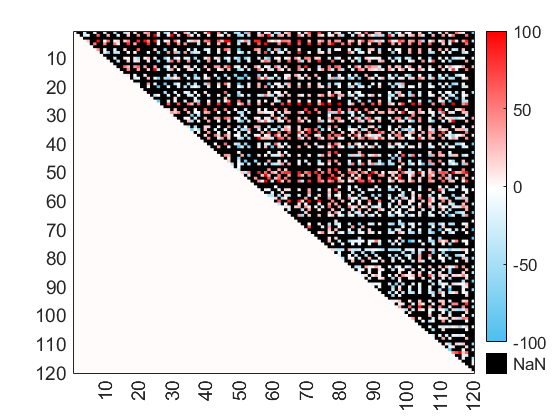

for i=1:120
    if rem(i,10)==0
        xticklable{i}=num2str(i);
        yticklable{i}=num2str(i);
    else
         xticklable{i}=' ';
         yticklable{i}=' ';
    end
end

g.YDisplayLabels=yticklable;
g.XDisplayLabels=xticklable;


% xtickangle(45); 

% ax = gca;
% ax.XDisplayLabels = nan(size(ax.XDisplayData));
% ax.YDisplayLabels = nan(size(ax.YDisplayData));
% imTest.Interpolation='bilinear';   % 插值
% h.FontColor = 'none';
% h.ColorLimits = [0.35 0.55];
% h.CellLabelFormat = '%0.2g';
% h.CellLabelColor = 'k';



**4. 统计IAM方法与FFM方法所计算的有效周期值**

Nev_IAM=zeros(20891,1); % Number of effective value 存储有效值个数
for i=1:20891
    eleChange=Grid_EC(i).eleChange;
    Nev_IAM(i)=sum(~isnan(eleChange(:)));
end



Nev_FFM=zeros(20891,1); % Number of effective value 存储有效值个数
for i=1:20891
    eleChange=Grid_EC_FFM(i).eleChange;
    Nev_FFM(i)=sum(~isnan(eleChange(:)));
end

A= Grid_EC(450).eleChange;
x = (1:120)';
nan_rows = find(isnan(A));
x(nan_rows,:)=[];
A(nan_rows,:)=[];

coefficients = polyfit(x, A, 1);



C = Nev_IAM - Nev_FFM;               % 计算差矩阵
% 对A进行排序，返回排序后的结果B和索引I

SD=[Nev_IAM,Nev_FFM,C];

[B, I] = sort(C, 'descend'); % 对A进行排序，返回排序后的结果B和索引I

[maxC, ind] = max(C(:)); % 找到差矩阵的最大值及其所在位置
[row, col] = ind2sub(size(C), ind); % 将位置转换为行列坐标


figure;
box on;
hold on;
set(gca,'FontName','Arial');
set(gca,'FontSize',14);
edges = (0:5:120);
h1 = histogram(Nev_FFM(:,1),edges);
h2 = histogram(Nev_IAM(:,1),edges);
% h3 = histogram(adj2(:,3),edges);

h2.FaceColor = [232 65 24]/255;
h2.FaceColor = [190 190 190]/255;
h2.FaceAlpha = 0.8;
% h3.FaceAlpha = 0.7;
legend('FFM Algorithm','IAM Algorithm');
ylabel('Number of Grids');
xlabel('Effective Cycles');


4. 绘制高程

temp=[];
for i=48:48
    a=Ross_D202001(i).coordinate;
    temp=[temp;a];
end


figure;
colormap(CustomColormap) 
h=scatter(temp(:,1),temp(:,2),12,temp(:,3),'filled');
caxis([-20 100]);

hold on ;
dh=zeros(20891,3)*nan;
for i=1:20891
    dh(i,1)=RossGrid5_5km(i).long;
    dh(i,2)=RossGrid5_5km(i).lat;
    temp=Grid_EC(i).eleChange;
    if ~isempty(temp)
       temp=temp(109);
       if abs(temp)<300
          dh(i,3)=temp;
       end
    end
end
find(abs(dh(:,3))<250);
h=scatter(dh(:,1),dh(:,2),12,dh(:,3),'filled');
% caxis([-100 100]);

hold on ;

plot(Boundary(:,1),Boundary(:,2),'k'); 

5. Ronne 冰架测试

figure; 
plot(Boundary(1:end,1),Boundary(1:end,2),'k','MarkerSize',0.01,'HandleVisibility','off'); 

lon=Ronne_inside_grid_5km(1,1);
lat=Ronne_inside_grid_5km(1,2);

hold on;
scatter(lon,lat,20,'filled');

% CP=Ronne_201101_202012.coordinate;

% for i=1:1349
%     CP(i,:)=Ronne_201101_202012(i).coordinate;
% end

scatter(CP(:,1),CP(:,2),5,'filled');